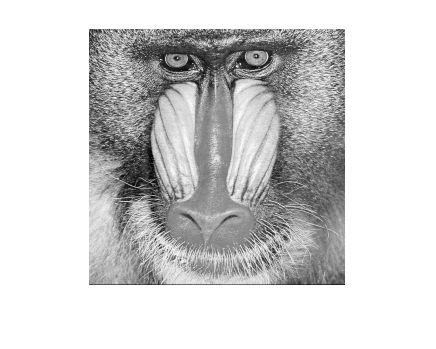

%İsmet Emir Demir 180315070
clearvars;
close all;
clc;

I = imread("70.tif");
imshow(I,[]);

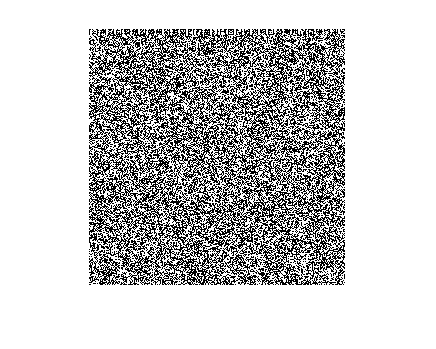

Ib = bitget(I,1);
imshow(Ib,[]);

A=(Ib)';
A=(A(:))';
Array = {};
word={};
Stop = [0,0,1,0,0,1,0,0];
for i=1:8:65000 
    c = A(i:i+7);
    Array(end+1) ={c};
    if (isequal(c,Stop))
        break
    end
end
for j=1:length(Array)
 word{j}=char(bin2dec(num2str(cell2mat(Array(j)))));
end
flip(cell2mat(word))

ans = '$One mode of failure is continually overlooking simple ideas while searching for a better way. One mode of success is continually practicing simple ideas while searching for a better way.'